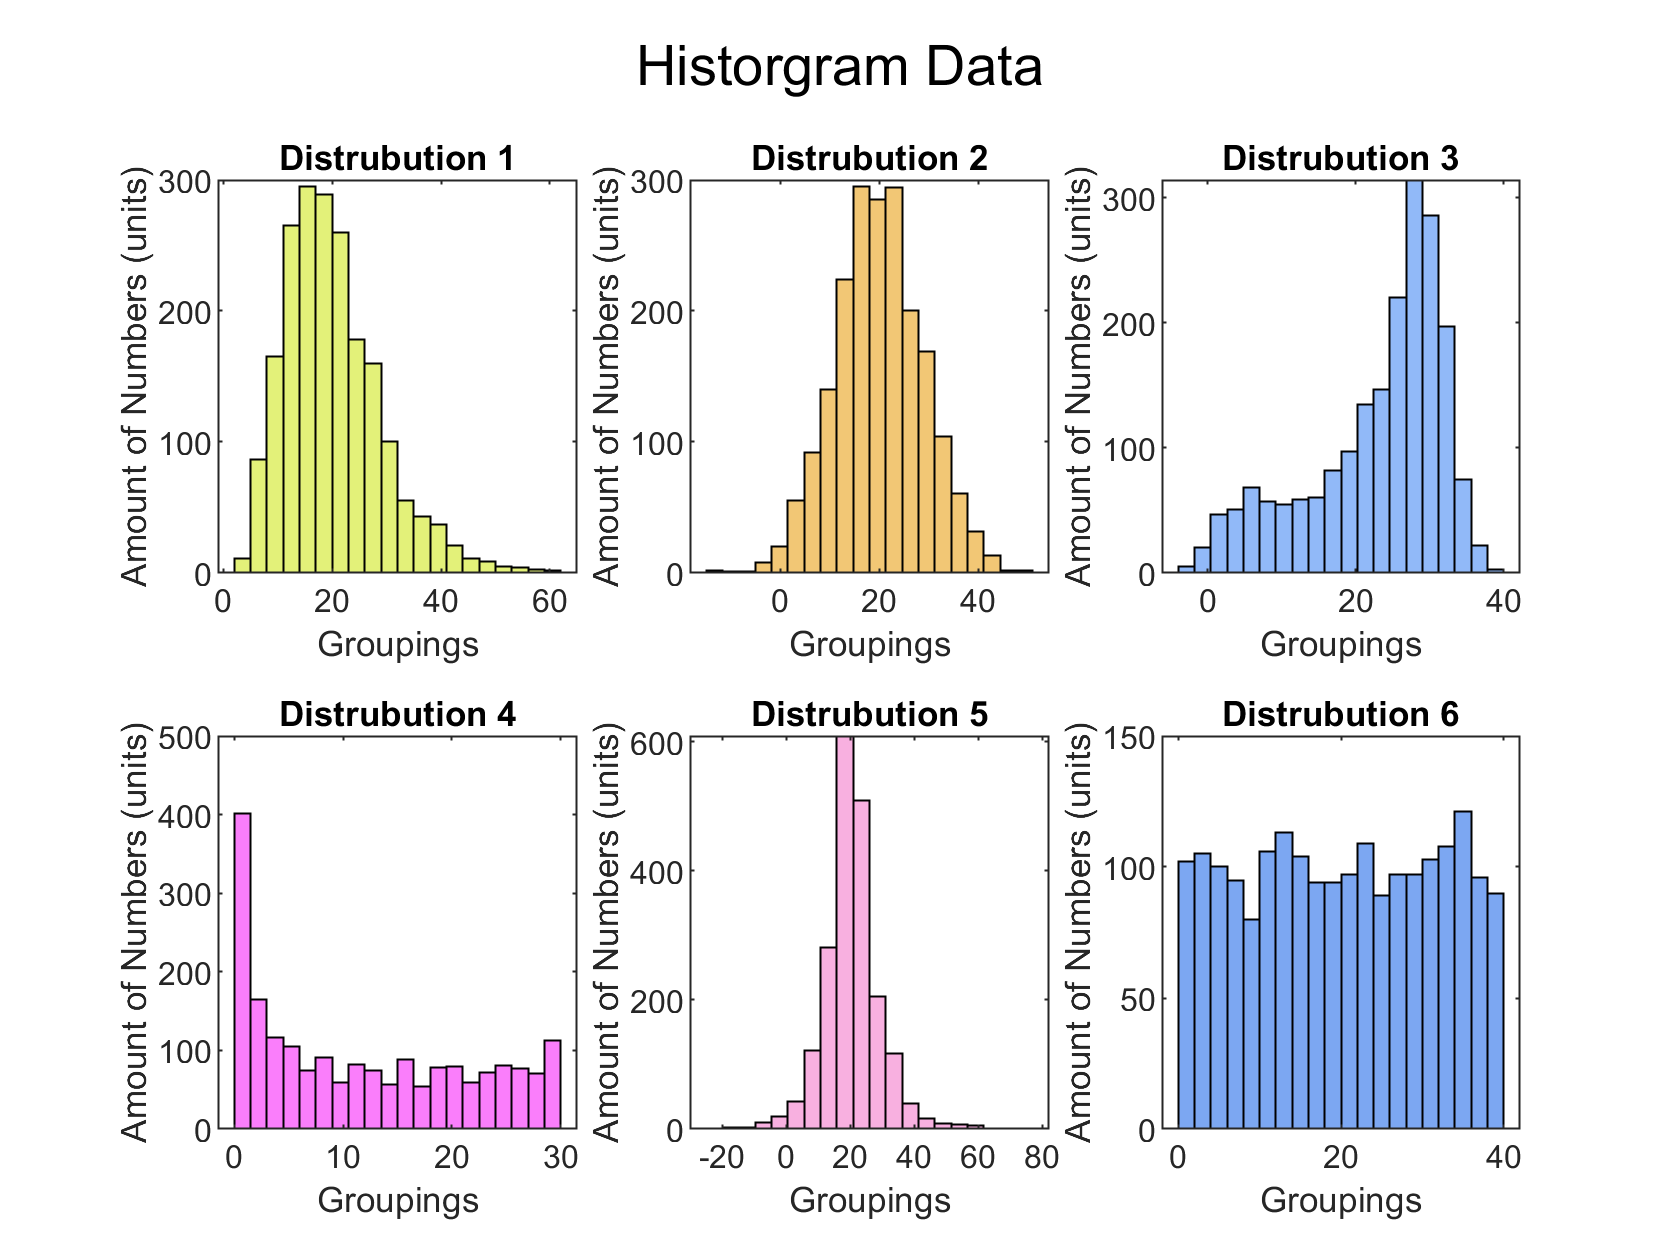

clc 
clear
%Load in Data 
tic
load 'Project2.mat'

%Determine number of distributions 

length = size(data,2);

%Generate for loop to plot all distributions, give them different colors, and name them 

for i = 1:length

%Generate random RGB numbers for graphs 
   
    R = rand(1);  G = rand(1);  B = rand(1);

%Generate figures for each distrubution form data set 
%and assign them names and face colors  
   
   SubplotDis = subplot((length/3),3, i , "replace"); 
    histogram(data(:,i),20,'facecolor', [R G B]);
    title(sprintf('Distribution %d', i)); 
    xlabel(" Groupings ");
    ylabel("Amount of Numbers (units)");
end
%adding title to overall subplot 

suptitle('Histogram Data')


%set up array for mean 

Mean = ones(length,1);
Var = ones(length,1);
Skew = ones(length,1);
Kurt = ones(length,1);

for  i = 1:size(data,2);
[Mean(i) Var(i) Skew(i) Kurt(i)] = functionMeanVarSkewKurt(data(:,i));
fprintf("Distribution %d has a mean of %2.2f, variance of %2.2f, a skewness of %2.2f, and a Kurtosis of %2.2f\n\n", i, Mean(i), Var(i), Skew(i), Kurt(i));
end

Distribution 1 has a mean of 20.14, variance of 79.87, a skewness of -0.95, and a Kurtosis of 4.32

Distribution 2 has a mean of 20.02, variance of 79.16, a skewness of -0.01, and a Kurtosis of 3.06

Distribution 3 has a mean of 22.89, variance of 83.64, a skewness of 0.92, and a Kurtosis of 2.91

Distribution 4 has a mean of 11.87, variance of 96.56, a skewness of -0.36, and a Kurtosis of 1.72

Distribution 5 has a mean of 20.52, variance of 77.89, a skewness of -0.31, and a Kurtosis of 6.44

Distribution 6 has a mean of 20.08, variance of 134.17, a skewness of 0.02, and a Kurtosis of 1.78



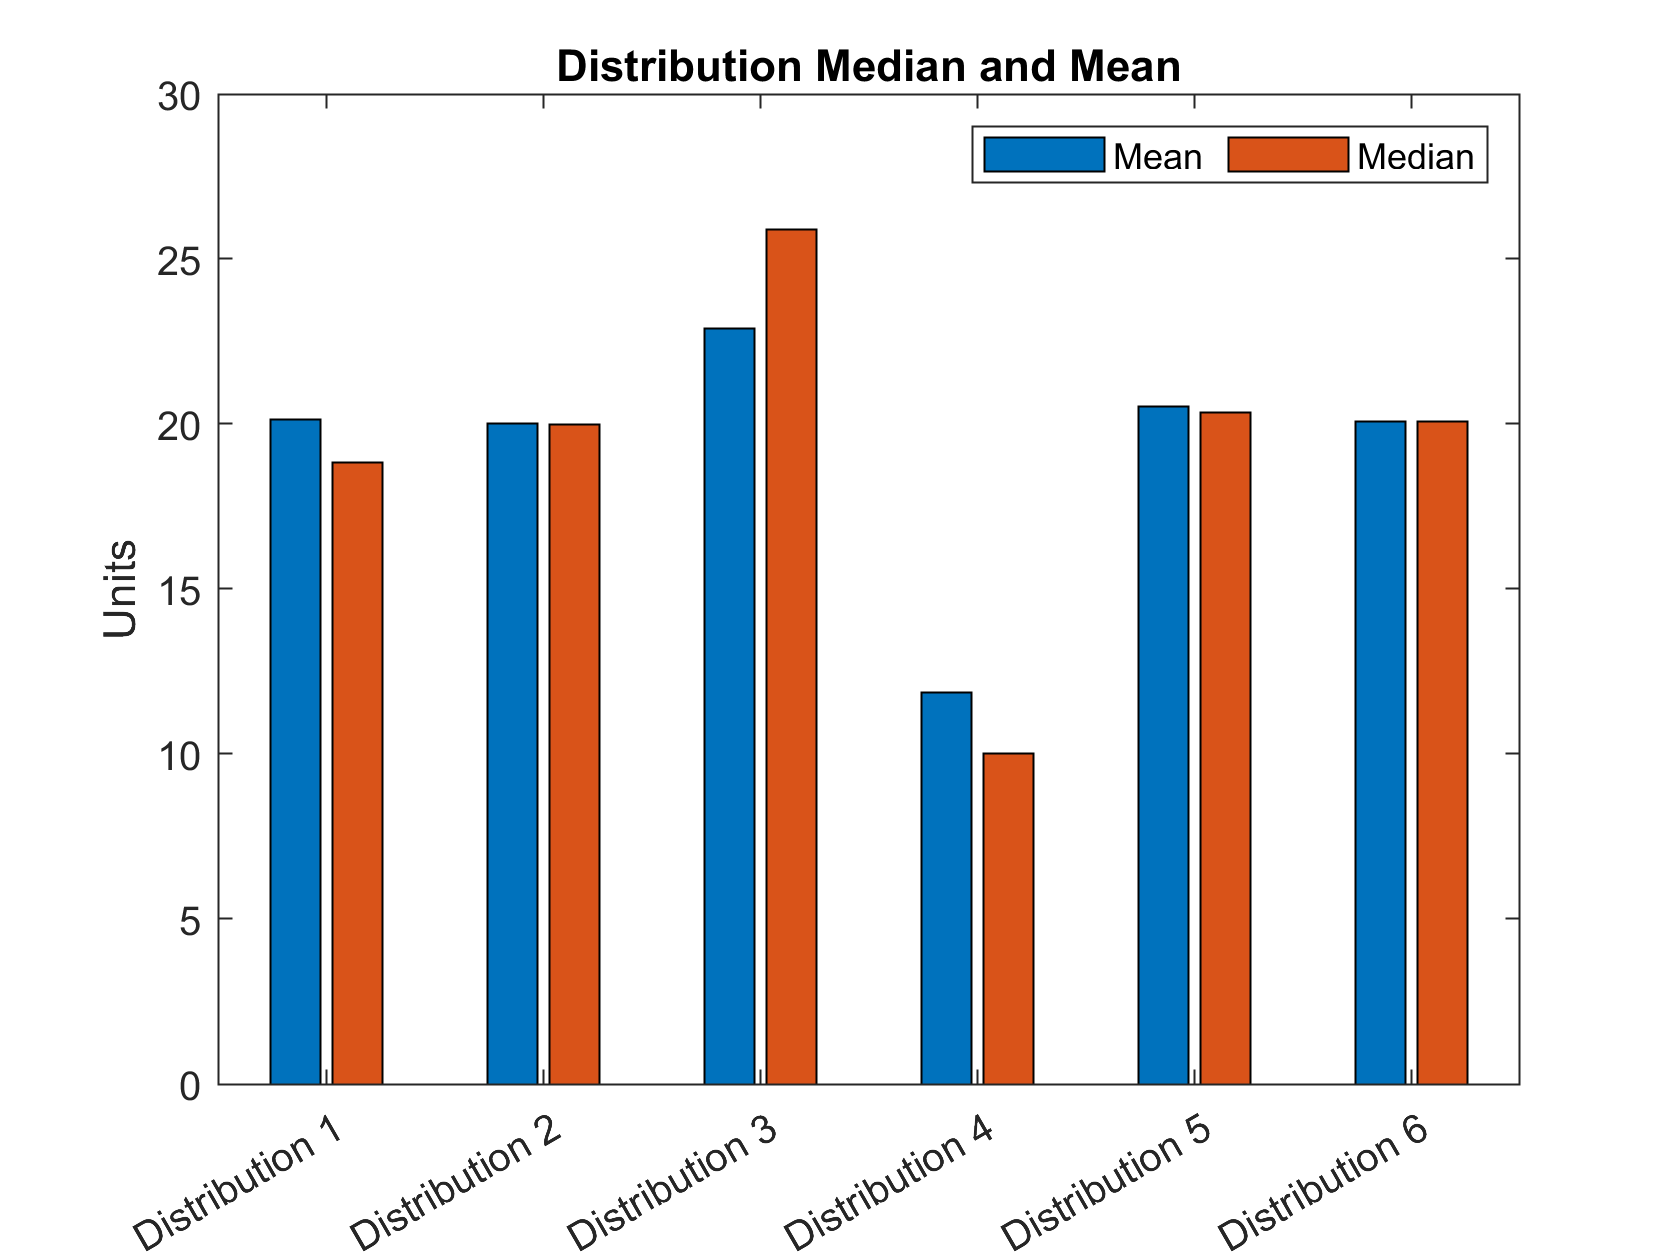

mean4graph=ones(1,length);
median4graph=ones(1,length);

    for i = 1:length;
      mean4graph(i) = mean(data(:,i));
      median4graph(i) = median(data(:,i));
      xAxisfor(i) = string(sprintf('Distribution %d', i));
  end
figure
 xAxis = categorical(xAxisfor);
 xAxis = reordercats(xAxis,xAxisfor);
 data4graph = [ mean4graph; median4graph]';
 bar(xAxis,data4graph);
 title("Distribution Median and Mean");
 legend("Mean", "Median", 'Orientation', "horizontal");
 ylabel("Units")

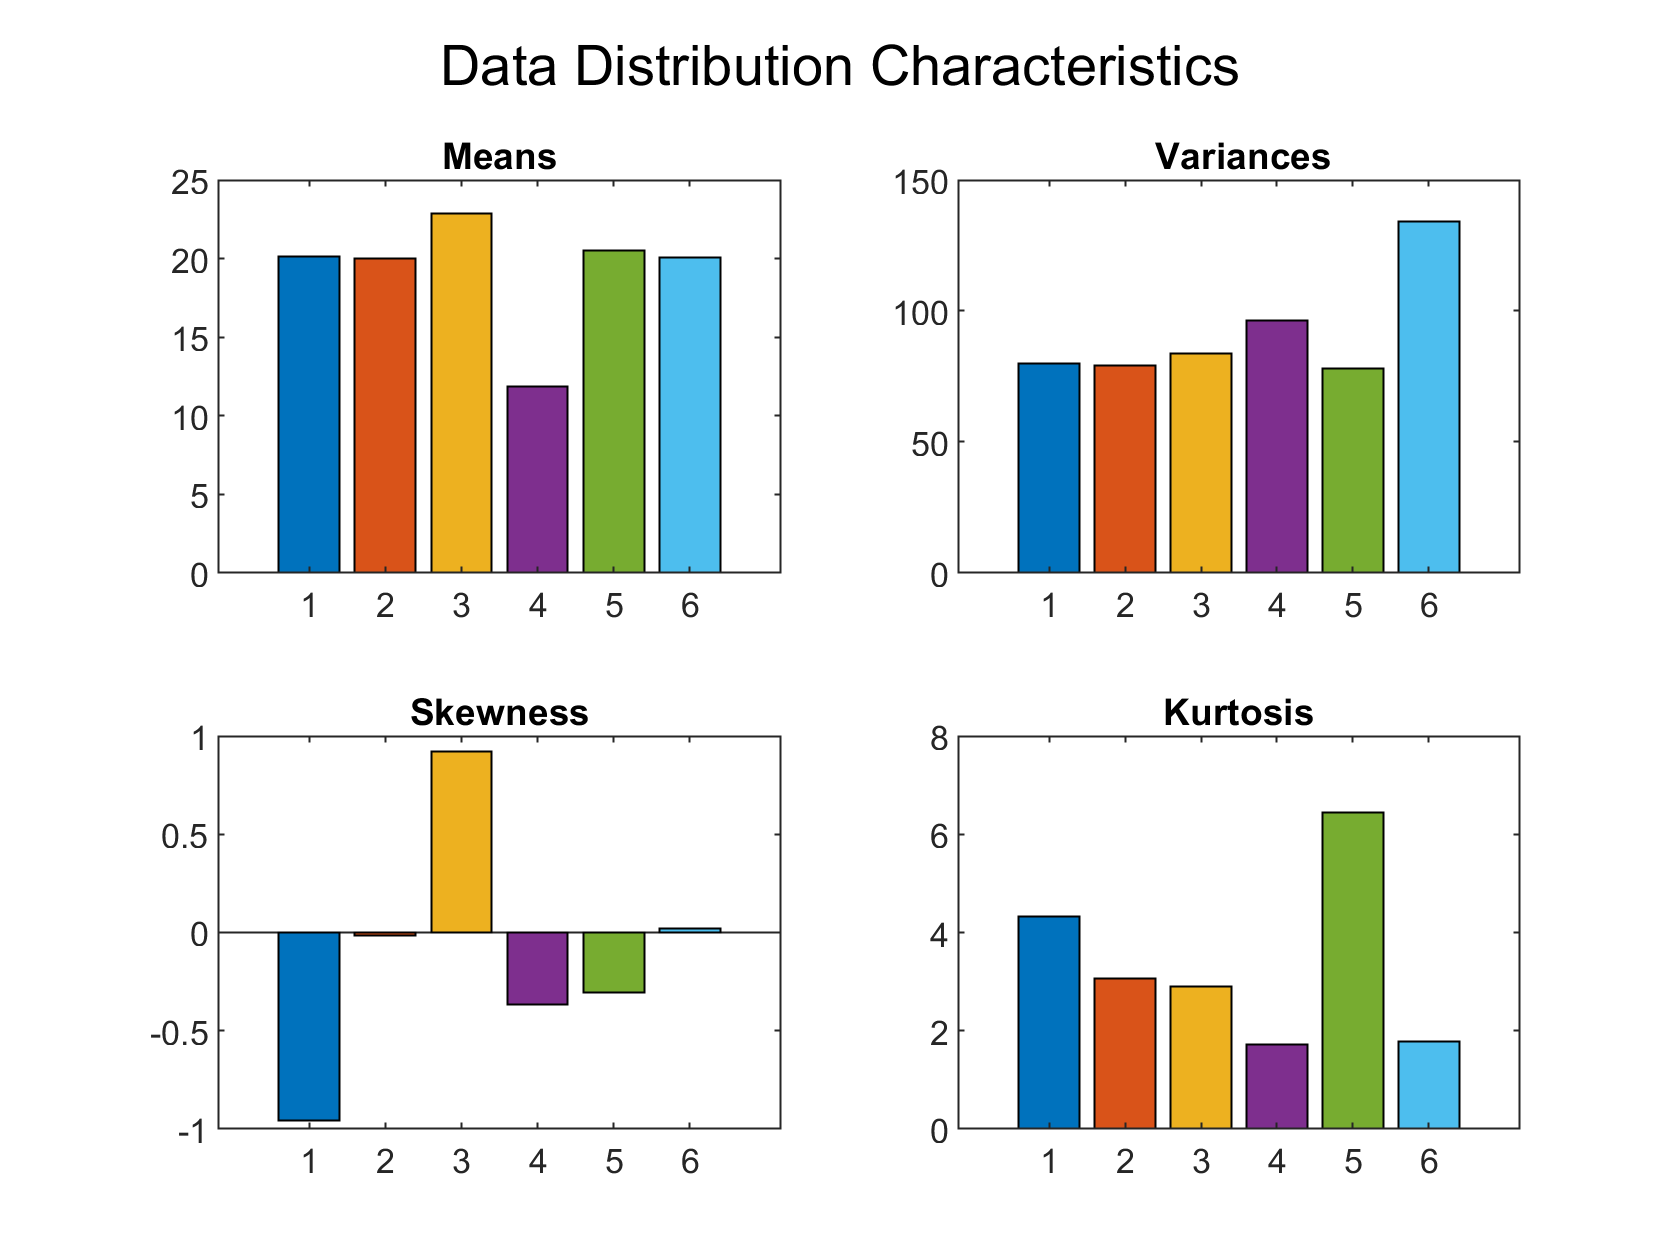

figure  
lengthx = 1:length;
for i = 1:4
    switch i

        case 1
            subplot(2,2,1)
           bar(lengthx,diag(Mean), 'stacked')
           title("Means")
        case 2 
           subplot(2,2,2)
           bar(lengthx, diag(Var), 'stacked')
           title(" Variances")
        case 3 
          subplot(2,2,3) 
            bar(lengthx, diag(Skew), 'stacked')
           title("Skewness")
        case 4 
            subplot(2,2,4)
             bar(lengthx, diag(Kurt), 'stacked')
            title("Kurtosis")
    end
        
end
suptitle("Data Distribution Characteristics");

toc

Elapsed time is 39.340330 seconds.
